tic

%%Load data and parameters
PricesTT = PricesISTi ;
VolumesTT = VolumesISTi ;
leadPriceDays = 2;
lagPriceDays = 20;
PriceSMAtimes = -10 ;
leadVolDays = 2 ;
lagVolDays = 140 ;
VolSMAtimes = -50 ;
ValThresh = 10^5 ;
RebalanceFreq = 5;
TradingCosts = [0.2/100, 0.25/100];
InitWeights = [] ;
riskFreerate = 0; 
cashBorrowrate = 0; 
InitPortfolioValue = 10^6 ; 


% Build signal
% Trend following signal
leadPriceDays ; 
lagPriceDays ;
smaPriceLeadTT = movavg (PricesTT,'linear',leadPriceDays);
smaPriceLagTT = movavg (PricesTT,'linear',lagPriceDays);
smaPriceSignalTT = PricesTT ;
smaPriceSignalTT.Variables = smaPriceLeadTT.Variables * ((100+PriceSMAtimes)/100) > smaPriceLagTT.Variables ; 
clear smaPriceLeadTT smaPriceLagTT

% Volume liquidity signal
VolSMAtimes ;
leadVolDays ;
lagVolDays ;
smaVolLeadTT = movavg (VolumesTT,'linear',leadVolDays);
smaVolLagTT = movavg (VolumesTT,'linear',lagVolDays) ;
smaVolSignalTT = VolumesTT ;
smaVolSignalTT.Variables = smaVolLeadTT.Variables *((100+VolSMAtimes)/100) > smaVolLagTT.Variables ;
clear smaVolLeadTT smaVolLagTT

% Value liquidity signal
ValThresh ;
ValuesTT = VolumesTT ;
ValuesTT.Variables = PricesTT.Variables .* VolumesTT.Variables ;
ValThreshSignalTT = VolumesTT ;
ValThreshSignalTT.Variables = ValuesTT.Variables> ValThresh ;
clear ValuesTT

% Combined Signal
CombSignalTT = PricesTT ;
CombSignalTT.Variables = smaPriceSignalTT.Variables .* smaVolSignalTT.Variables .* ValThreshSignalTT.Variables ;

% Shift signal to avoif lookforwardbias
FinalSignalTT = CombSignalTT ;
FinalSignalTTvars = FinalSignalTT.Variables ;
CombSignalTTvars = CombSignalTT.Variables ;
FinalSignalTTvars (2:end,:) = CombSignalTTvars (1:end-1,:) ;
FinalSignalTTvars (1,:) = 0 ;
FinalSignalTT.Variables = FinalSignalTTvars ;


%% Build the strategy
% Create strategy object
TradingCosts ;
InitWeights ;
RebalanceFreq ;
RebalanceWeights = @(w,p,s) RebalanceWeightsFcn (w,p,s) ;
TradeStrategy = backtestStrategy ('TradeStrategy', ...
    RebalanceWeights, "RebalanceFrequency", RebalanceFreq, "TransactionCosts", ...
    TradingCosts, "InitialWeights", InitWeights) ;

% setup backtest engine
riskFreerate ; 
cashBorrowrate ; 
InitPortfolioValue ; 

backtester = backtestEngine (TradeStrategy, "RiskFreeRate", ...
    riskFreerate , "CashBorrowRate", cashBorrowrate, "InitialPortfolioValue", ...
    InitPortfolioValue) ;

% run the strategy backtest
startIdx = lagVolDays ;
% endIdx = datetime ('09-Jul-2021')  ;

backtester = runBacktest (backtester, PricesTT, FinalSignalTT, ...
    'Start', startIdx) ;


Performance Analysis

% Summary 
summaryTable = summary (backtester) 

summaryTable = 9×1 table
                       TradeStrategy
                       _____________

    TotalReturn            0.59554  
    SharpeRatio            0.23624  
    Volatility            0.020824  
    AverageTurnover        0.12433  
    MaxTurnover                  1  
    AverageReturn        0.0048948  
    MaxDrawdown           0.088986  
    AverageBuyCost          363.39  
    AverageSellCost         436.12  


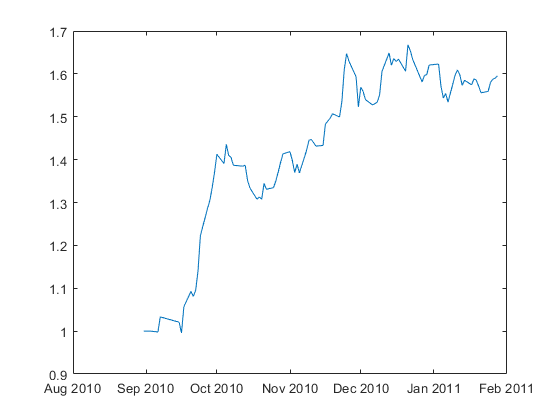

%Plot cumulative return 
dailyRet = backtester.Returns ; 
portfolioValue = ret2tick (dailyRet) ; 
plot (portfolioValue.Time, portfolioValue.Variables) 

% semilogy(portfolioValue.Time, portfolioValue.Variables) 
% equityCurve(backtester) 

MAR = 0 ; 

% MaxDailyRet = max (dailyRet.Variables) ; 
% MinDailyRet = min (dailyRet.Variables) ; 
% a = CumSumPort.DailyReturnPort; 
EndCumSum = portfolioValue(end, :)  ;
EndCumSumVar = - EndCumSum.Variables

EndCumSumVar = -1.5955

% MaxCumSum = max (CumSumPort.DailyReturnPort) ; 
% MinCumSum = min (CumSumPort.DailyReturnPort) ; 

portfolioValueVar = portfolioValue.Variables ; 

TimePeriod = portfolioValue.Time ;
TradingPeriod = yearfrac (TimePeriod(1), TimePeriod(end))  

TradingPeriod = 0.4110

CAGR = -(portfolioValueVar(end) ^ (1/(TradingPeriod )) -1) ;
CAGR

CAGR = -2.1170

SharpeRatio = - sharpe(dailyRet.Variables, 0) * sqrt (250) ;
SharpeRatio (isnan(SharpeRatio)) = 0

SharpeRatio = -3.7353

Sortino = - (mean(dailyRet.Variables) - MAR) / sqrt(lpm(dailyRet.Variables, MAR, 2)) * sqrt (250) ;
% Sortino (isnan(Sortino)) = 0 ;
Sortino

Sortino = -7.5357

% [MaxDD,MaxDDIndex] =  maxdrawdown (portfolioValue.Variables); 
% MaxDD 
% StartEndMaxDD = TimePeriod (MaxDDIndex)
 

Latest signal from last trading day

% LatestSignal = FinalCombSignal (end,:); 
% a = LatestSignal.Variables ; 
% b = LatestSignal.Properties.VariableNames ; 
% SymSignal = b(a>0); 
% SymSignal = cell2table (transpose(SymSignal) ) ; 
% SymSignal.Properties.VariableNames = "Symbols Signal"; 

% SymSignal ;
% clear a b 

Write signal to output file

% writetable (SymSignal, "Trend Trading Input Output Data.xlsx", 'sheet', "Output Data")

Check section

toc

Elapsed time is 28.490353 seconds.


Local Functions

Equally Weighted Rebalance Function

function new_weights = RebalanceWeightsFcn (Current_Weights ,PriceTT , SignalTT) 
% Compute weights based on most recent signal.

% Pull out the signal
CrossoverSignal = SignalTT.Variables ;

% Bet sizing
UninvestedAssets = sum (CrossoverSignal(end, :)) ;
MinNSymDivers = 6;

if UninvestedAssets <= MinNSymDivers 
    new_weights = CrossoverSignal(end,:) * (1 / MinNSymDivers) ;
    new_weights (isnan(new_weights)) = 0 ;
    new_weights (isinf(new_weights)) = 0 ;
    else
    new_weights = CrossoverSignal(end,:) * (1 / UninvestedAssets) ;
    new_weights (isnan(new_weights)) = 0 ;
    new_weights (isinf(new_weights)) = 0 ;

end

end
